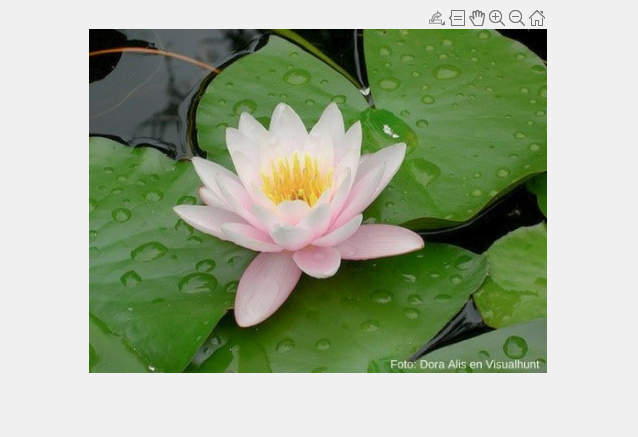

I = imread('flor.jpg');

imshow(I);

rect = getrect;

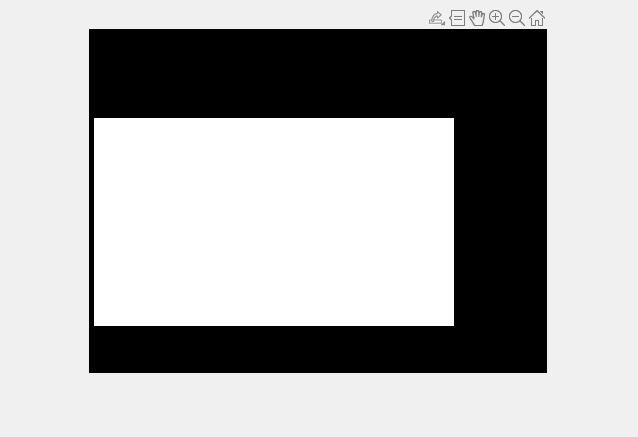


HSV = rgb2hsv(I);

[f, c, d] = size(I);

H = HSV(:,:,1)*2*pi;

Hx = cos(H);

Hy = sin(H);

S = HSV(:,:,2);

V = HSV(:,:,3);

Hx = reshape(Hx,[f*c,1]);
Hy = reshape(Hy,[f*c,1]);
S = reshape(S,[f*c,1]);
V = reshape(V,[f*c,1]);

O = [Hx Hy S V];

%RGB
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);
%O = double([R(:) G(:) B(:)]);

k=20;
C = kmeans(O,k);

MASK = zeros(f,c,1);
MASK(rect(2): rect(2) + rect(4), rect(1):rect(1)+rect(3),:) = 1;
imshow(MASK);

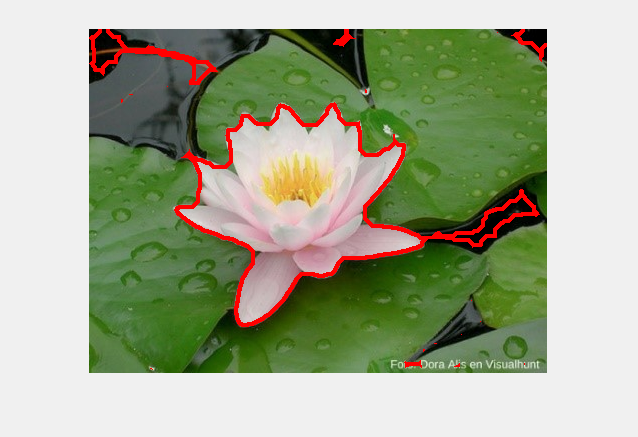


VEC_H = [C, MASK(:)];

Hist0 = zeros(1,k);
Hist1 = zeros(1,k);

for count = 1:f*c
    pos = VEC_H(count,1);
    res = VEC_H(count,2);
    if res
        Hist1(pos) = Hist1(pos)+ 1;
    else
        Hist0(pos) = Hist0(pos)+ 1;
    end
end

RES = Hist1*0.75 > Hist0*2;

M = zeros(f*c,1);

for count = 1:f*c
    pos = VEC_H(count,1);
    if RES(pos)
        M(count)=1;
    end
end
M = reshape(M,[f,c]);

disk = strel('disk',10);
M = imclose(M,disk);

disk = strel('disk',5);
M2 = imerode(M,disk);

MT = M-M2;

I = imoverlay(I,MT,'red');
imshow(I);


AUX = bwconncomp(M);
AUX

AUX = struct with fields:
    Connectivity: 8
       ImageSize: [344 458]
      NumObjects: 18
    PixelIdxList: {[2015×1 double]  [7×1 double]  [4×1 double]  [3×1 double]  [26890]  [30847×1 double]  [161×1 double]  [7×1 double]  [78×1 double]  [5×1 double]  [3×1 double]  [13×1 double]  [128274]  [131680]  [134797]  [140356]  [601×1 double]  [2×1 double]}


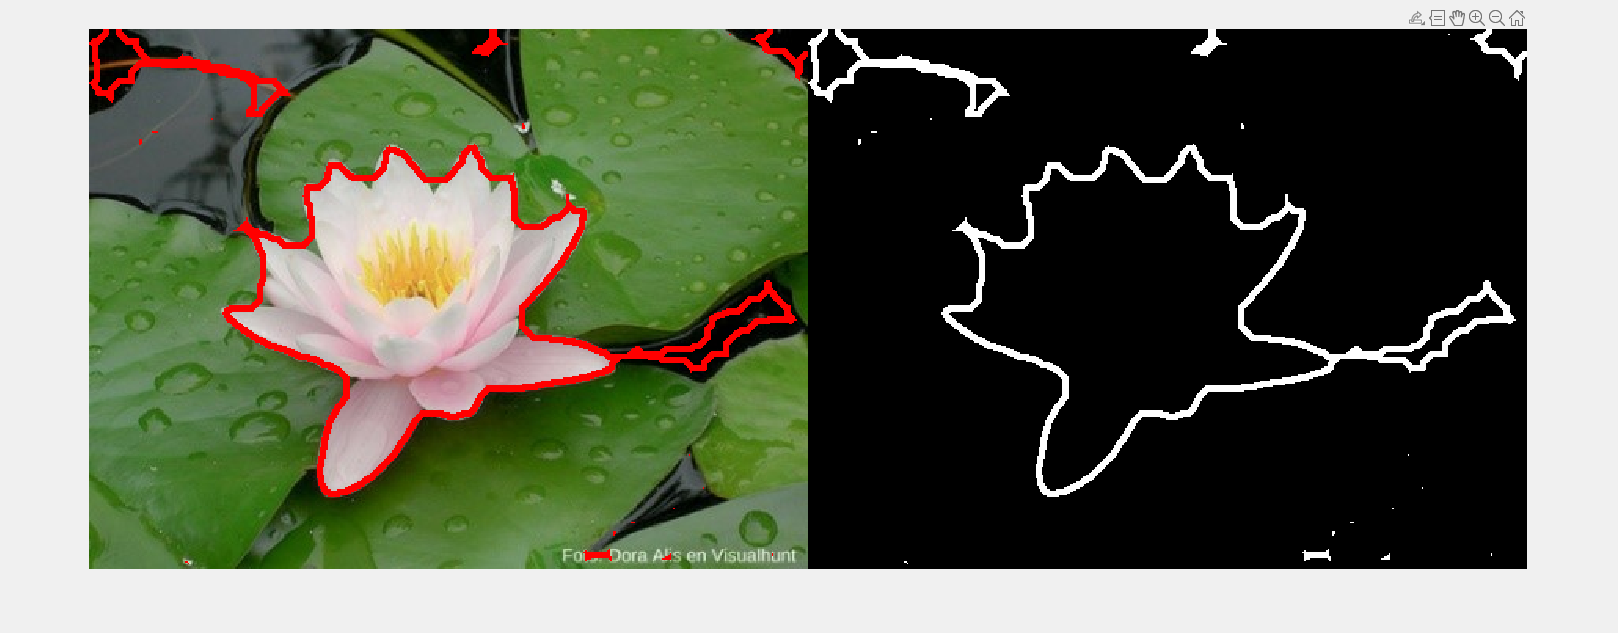


montage({I,MT});